clear;
close all;
clc;

dirname = 'C:/Users/sjtu_/Desktop/Condensate-Detection-main/_figs/20230421/';
BRB = [dirname 'BRB/'];
CC = [dirname 'CC/'];
Mix = [dirname 'Mix/'];

## Corn

CC_1 = calculate_angle([CC 'Sample1/20230421_CC_DFHO_1in20_5uM_s1_allMeasurements.csv']);
CC_2 = calculate_angle([CC 'Sample2/20230421_CC_DFHO_1in20_5uM_s2_allMeasurements.csv']);
CC_3 = calculate_angle([CC 'Sample3/20230421_CC_DFHO_1in20_5uM_s3_allMeasurements.csv']);
CC_full = cat(1, CC_1, CC_2, CC_3);

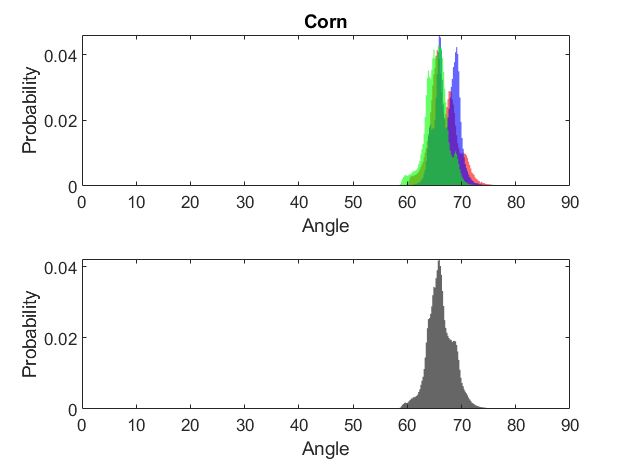

figure;
subplot(2,1,1);
plotHistogram(CC_1,'r');
hold on 
plotHistogram(CC_2,'b');
hold on 
plotHistogram(CC_3,'g');
hold off
title("Corn");
subplot(2,1,2);
plotHistogram(CC_full,'k');
% f = gcf;
% exportgraphics(f, [dirname 'SI_Corn.eps'],'Resolution',72)

## Red Broccoli

BRB_1 = calculate_angle([BRB 'Sample1/20230421_BRB_DFHO_1in20_5uM_s1_allMeasurements.csv']);
BRB_2 = calculate_angle([BRB 'Sample2/20230421_BRB_DFHO_1in20_5uM_s2_allMeasurements.csv']);
BRB_3 = calculate_angle([BRB 'Sample3/20230421_BRB_DFHO_1in20_5uM_s3_allMeasurements.csv']);
BRB_full = cat(1, BRB_1, BRB_2, BRB_3);

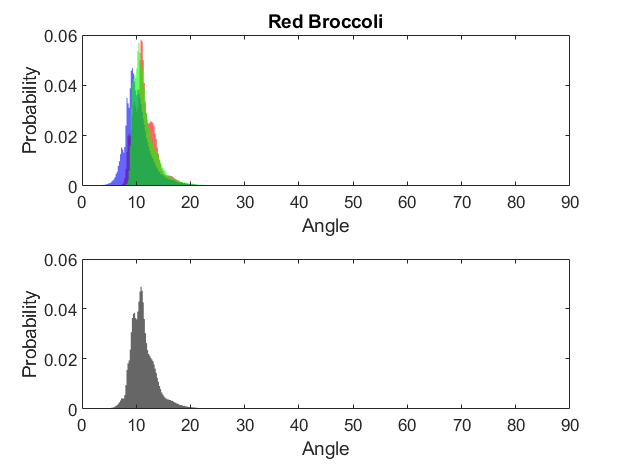

figure;
subplot(2,1,1);
plotHistogram(BRB_1,'r');
hold on
plotHistogram(BRB_2,'b');
hold on 
plotHistogram(BRB_3,'g');
hold off
title("Red Broccoli");
subplot(2,1,2);
plotHistogram(BRB_full,'k');
% f = gcf;
% exportgraphics(f, [dirname 'SI_RedBroccoli.eps'],'Resolution',72)

## Mix

mix_1 = calculate_angle([Mix 'Sample1/20230421_Mix_DFHO_1in20_both5uM_s1_allMeasurements.csv']);
mix_2 = calculate_angle([Mix 'Sample2/20230421_Mix_DFHO_1in20_both5uM_s2_allMeasurements.csv']);
mix_3 = calculate_angle([Mix 'Sample3/20230421_Mix_DFHO_1in20_both5uM_s3_allMeasurements.csv']);
mix_full = cat(1, mix_1, mix_2, mix_3);

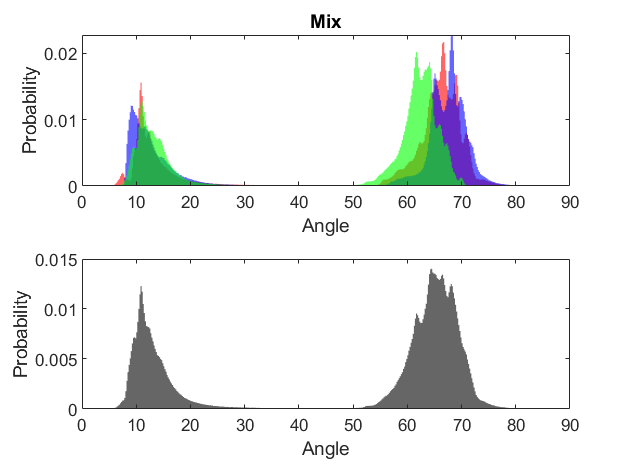

figure;
subplot(2,1,1);
plotHistogram(mix_1,'r');
hold on
plotHistogram(mix_2,'b');
hold on
plotHistogram(mix_3,'g');
hold off
title("Mix");
subplot(2,1,2);
plotHistogram(mix_full,'k');
% f = gcf;
% exportgraphics(f, [dirname 'SI_Mix.eps'],'Resolution',72)

## Plotting results

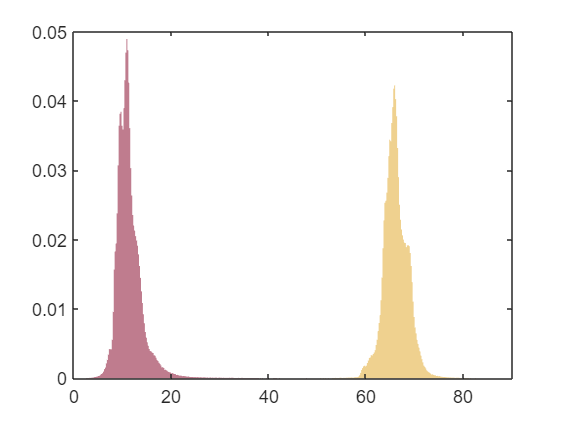

figure;
plotHistogram(BRB_full,"#BF7C8E");
hold on
plotHistogram(CC_full, "#EFD18F");
hold off

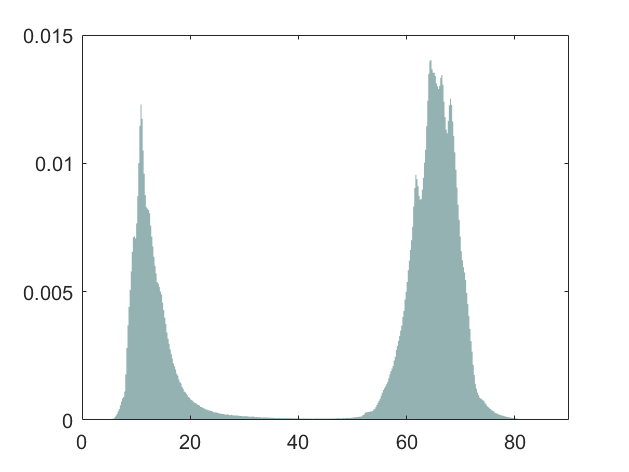

% f = gcf;
% exportgraphics(f, [dirname 'Figure 3_panel F_separate.eps'],'Resolution',72)

figure;
plotHistogram(mix_full,'#94B2B2');

% f = gcf;
% exportgraphics(f, [dirname 'Figure 3_panel F_Mix.eps'],'Resolution',72)

function angle = calculate_angle(fn)
    temp = readmatrix(fn);
    CY3 = temp(:,2) - min(temp(:,2));
    GFP = temp(:,3) - min(temp(:,3));
    angle = rad2deg(atan(GFP./CY3));
end


function plotHistogram(fullAngle,faceColor)
    histogram(fullAngle,"Normalization","probability","BinEdges",[0:0.2:90],"FaceColor",faceColor,"EdgeColor","none",FaceAlpha=0.6);
    xlim([0 90]);
%    ylim([0 0.004]);
    ylabel("Probability");
    xlabel("Angle");
%     set(gca,'xtick',[])
%     set(gca,'xticklabel',[])
%     yticks([0, 0.02, 0.04]);
%     set(gca,'yticklabel',[])
end